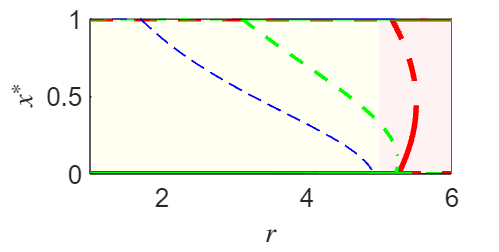

clear all


p = 0.3;
deltas = [0.3, 0.6, 0.9];
colors = {'r', 'g', 'b'};
line_widths = [3, 2, 1];
r_range = 1:0.01:6;
k = 4;

figure
hold on;
hold on;
set(gcf, 'Position', [64, 583, 363, 183]);


x1 = [1.02, 5, 5, 1.02];
y1 = [0, 0, 1, 1];
patch(x1, y1, [1 1 0.95], 'EdgeColor', 'none');


x2 = [5, 5.99, 5.99, 5];
y2 = [0, 0, 1, 1];
patch(x2, y2, [1 0.95 0.95], 'EdgeColor', 'none');

for delta_idx = 1:length(deltas)
    delta = deltas(delta_idx);
    color = colors{delta_idx};
    line_width = line_widths(delta_idx);

    % Initialize storage variables
    solid_x_values = [];
    solid_y_values = [];
    dashed_x_values = [];
    dashed_y_values = [];
    horizontal_line_change_r_0 = 6;
    horizontal_line_change_r_1 = 6;

    for r = r_range
        % Define the functions
        phi1 = @(x) phi1_func(x, p, delta, k, r);
        phi2 = @(x) phi2_func(x, p, delta, k, r);
        phi3 = @(x) phi3_func(x, p, delta, k, r);
        phi4 = @(x) phi4_func(x, p, delta, k, r);
        eqn = @(x) x * (1 - x) * (phi1(x) - phi2(x) - phi3(x) + phi4(x) - (k - 2) * x * (phi2(x) - phi4(x)));


        x_prev = 0;
        f_prev = eqn(x_prev);
        zero_points = [];
        for x = 0.001:0.001:0.999
            f = eqn(x);
            if f_prev * f < 0 % Sign change, found zero point
                zero_points = [zero_points, x]; % Record zero point
            end
            x_prev = x;
            f_prev = f;
        end

        if length(zero_points) >= 1
            if horizontal_line_change_r_1 == 6
                horizontal_line_change_r_1 = r;
            end
            if length(zero_points) == 1
                dashed_x_values = [dashed_x_values, r];
                dashed_y_values = [dashed_y_values, zero_points];
            elseif length(zero_points) == 2
                solid_x_values = [solid_x_values, r];
                solid_y_values = [solid_y_values, zero_points(1)];
                dashed_x_values = [dashed_x_values, r];
                dashed_y_values = [dashed_y_values, zero_points(2)];
                if horizontal_line_change_r_0 == 6
                    horizontal_line_change_r_0 = r;
                end
            end
        end
    end

    plot(solid_x_values, solid_y_values, [color '-'], 'LineWidth', line_width);
    plot(dashed_x_values, dashed_y_values, [color '--'], 'LineWidth', line_width);

    plot([1, horizontal_line_change_r_0], [0, 0], [color '-'], 'LineWidth', line_width, 'HandleVisibility', 'off');
    plot([horizontal_line_change_r_0, 6], [0, 0], [color '--'], 'LineWidth', line_width, 'HandleVisibility', 'off');

    plot([1, horizontal_line_change_r_1], [1, 1], [color '--'], 'LineWidth', line_width, 'HandleVisibility', 'off');
    plot([horizontal_line_change_r_1, 6], [1, 1], [color '-'], 'LineWidth', line_width, 'HandleVisibility', 'off');
end

axis([1, 6, 0, 1]);

hold off;

xlabel('${r}$','Interpreter','latex', 'FontSize', 12);
ylabel('${x^*}$','Interpreter','latex', 'FontSize', 12);
set(gca, 'FontName', 'Arial'); 
set(gca, 'FontSize', 14); 
box on;

function val = phi1_func(x, p, delta, k, r)
    val = (r / ((k + 1) * delta)) * (((k-2)*x+1)*((1 + delta) * (lam1(x, p, delta, k) - lam2(x, p, delta, k)) - (1 - delta) * (lam3(x, p, delta, k) - lam4(x, p, delta, k))) + (lam1(x, p, delta, k) - lam2(x, p, delta, k) - lam3(x, p, delta, k) + lam4(x, p, delta, k)) + delta * (k - 1) * (lam2(x, p, delta, k) + lam4(x, p, delta, k))) - (k + 1);
end

function val = phi2_func(x, p, delta, k, r)
    val = (r / ((k + 1) * delta)) * (lam1(x, p, delta, k) - lam2(x, p, delta, k) - lam3(x, p, delta, k) + lam4(x, p, delta, k));
end

function val = phi3_func(x, p, delta, k, r)
    val = (r / ((k + 1) * delta)) * ((k - 2) * x * (lam1(x, p, delta, k) - lam2(x, p, delta, k) - lam3(x, p, delta, k) + lam4(x, p, delta, k)) - delta * (k - 1) * (lam2(x, p, delta, k) + lam4(x, p, delta, k))) + k + 1;
end

function val = phi4_func(x, p, delta, k, r)
    val = (r / ((k + 1) * delta)) * ((1 + delta) * (lam1(x, p, delta, k) - lam2(x, p, delta, k)) - (1 - delta) * (lam3(x, p, delta, k) - lam4(x, p, delta, k)));
end

function lam1 = lam1(x, p, delta, k)
    lam1 = p * (1 + delta) * (1 + (((k - 2) * x + 1) / (k - 1)) * delta)^(k - 1);
end

function lam2 = lam2(x, p, delta, k)
    lam2 = p * (1 + (((k - 2) * x) / (k - 1)) * delta)^(k - 1);
end

function lam3 = lam3(x, p, delta, k)
    lam3 = (1 - p) * (1 - delta) * (1 - (((k - 2) * x + 1) / (k - 1)) * delta)^(k - 1);
end

function lam4 = lam4(x, p, delta, k)
    lam4 = (1 - p) * (1 - (((k - 2) * x) / (k - 1)) * delta)^(k - 1);
end
